clc
clear
close all

ws = [-30 100 -100 100 -20 70]/3;

plot_options0 = {'workspace',ws,'scale',.5,'view',[-5 25]...
    ,'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
L0=4

L0 = 4

L1=10.5

L1 = 10.5000

L2=10.5

L2 = 10.5000

L3=6.5

L3 = 6.5000


L(1) = Link('revolute','d',L0,'a',0,'alpha',pi/2,'offset',0,'standard');
L(2) = Link('revolute','d',0,'a',L1,'alpha',0,'offset',pi/2,'standard');
L(3) = Link('revolute','d',0,'a',L2,'alpha',0,'offset',-80*pi/180,'standard');
L(4) = Link('revolute','d',0,'a',L3,'alpha',0,'offset',0,'standard');

Robot0 = SerialLink(L,'name','Robot RRRR','plotopt',plot_options0)

 
Robot0 = 
 
Robot RRRR (4 axis, RRRR, stdDH, slowRNE)                        
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          4|          0|      1.571|          0|
|  2|         q2|          0|       10.5|          0|      1.571|
|  3|         q3|          0|       10.5|          0|     -1.396|
|  4|         q4|          0|        6.5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1           

Robot0.tool=trotz(pi/2)*trotx(pi/2)

 
Robot0 = 
 
Robot RRRR (4 axis, RRRR, stdDH, slowRNE)                        
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          4|          0|      1.571|          0|
|  2|         q2|          0|       10.5|          0|      1.571|
|  3|         q3|          0|       10.5|          0|     -1.396|
|  4|         q4|          0|        6.5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  0  0  1  0              
          0         0  1  0  0           1  0  0  0              
       9.81         0  0  1  0           0  1  0  0              
                    0  0  0  1           0  0  0  1           

Robot0.trchain

ans = 'Rz(q1)Tz(4)Rx(90)Rz(q2)Tx(10.5)Rz(q3)Tx(10.5)Rz(q4)Tx(6.5)'

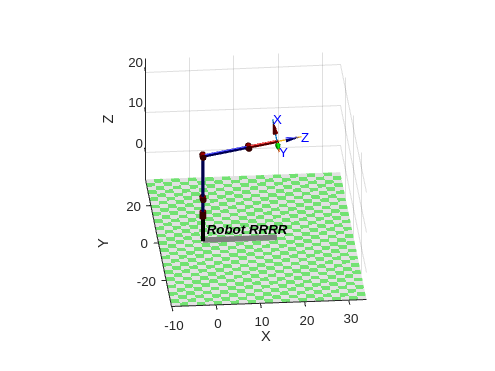

figure(1)
Robot0.plot([0 0 0 0])

NOA=Robot0.trchain

NOA = 'Rz(q1)Tz(4)Rx(90)Rz(q2)Tx(10.5)Rz(q3)Tx(10.5)Rz(q4)Tx(6.5)'

plot_options1 = {'workspace',ws,'scale',.5,'view',[-5 25]...
    ,'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
Robot1 = SerialLink(L,'name','Robot RRRR','plotopt',plot_options1)

 
Robot1 = 
 
Robot RRRR (4 axis, RRRR, stdDH, slowRNE)                        
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          4|          0|      1.571|          0|
|  2|         q2|          0|       10.5|          0|      1.571|
|  3|         q3|          0|       10.5|          0|     -1.396|
|  4|         q4|          0|        6.5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1           

Robot1.tool=trotz(pi/2)*trotx(pi/2)

 
Robot1 = 
 
Robot RRRR (4 axis, RRRR, stdDH, slowRNE)                        
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          4|          0|      1.571|          0|
|  2|         q2|          0|       10.5|          0|      1.571|
|  3|         q3|          0|       10.5|          0|     -1.396|
|  4|         q4|          0|        6.5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  0  0  1  0              
          0         0  1  0  0           1  0  0  0              
       9.81         0  0  1  0           0  1  0  0              
                    0  0  0  1           0  0  0  1           

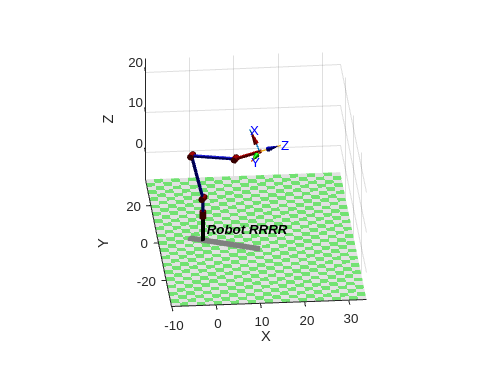

%figure(2)
Robot1.plot([-25*pi/180 15*pi/180 -20*pi/180 20*pi/180])


plot_options2 = {'workspace',ws,'scale',.5,'view',[-5 25]...
    ,'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
Robot2 = SerialLink(L,'name','Robot RRRR','plotopt',plot_options2)

 
Robot2 = 
 
Robot RRRR (4 axis, RRRR, stdDH, slowRNE)                        
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          4|          0|      1.571|          0|
|  2|         q2|          0|       10.5|          0|      1.571|
|  3|         q3|          0|       10.5|          0|     -1.396|
|  4|         q4|          0|        6.5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1           

Robot2.tool=trotz(pi/2)*trotx(pi/2)

 
Robot2 = 
 
Robot RRRR (4 axis, RRRR, stdDH, slowRNE)                        
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          4|          0|      1.571|          0|
|  2|         q2|          0|       10.5|          0|      1.571|
|  3|         q3|          0|       10.5|          0|     -1.396|
|  4|         q4|          0|        6.5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  0  0  1  0              
          0         0  1  0  0           1  0  0  0              
       9.81         0  0  1  0           0  1  0  0              
                    0  0  0  1           0  0  0  1           

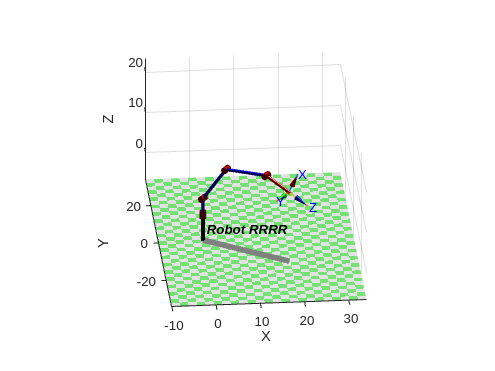

%figure(3)
Robot2.plot([-35*pi/180 -35*pi/180 30*pi/180 -30*pi/180])


plot_options3 = {'workspace',ws,'scale',.5,'view',[-5 25]...
    ,'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
Robot3 = SerialLink(L,'name','Robot RRRR','plotopt',plot_options3)

 
Robot3 = 
 
Robot RRRR (4 axis, RRRR, stdDH, slowRNE)                        
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          4|          0|      1.571|          0|
|  2|         q2|          0|       10.5|          0|      1.571|
|  3|         q3|          0|       10.5|          0|     -1.396|
|  4|         q4|          0|        6.5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1           

Robot3.tool=trotz(pi/2)*trotx(pi/2)

 
Robot3 = 
 
Robot RRRR (4 axis, RRRR, stdDH, slowRNE)                        
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          4|          0|      1.571|          0|
|  2|         q2|          0|       10.5|          0|      1.571|
|  3|         q3|          0|       10.5|          0|     -1.396|
|  4|         q4|          0|        6.5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  0  0  1  0              
          0         0  1  0  0           1  0  0  0              
       9.81         0  0  1  0           0  1  0  0              
                    0  0  0  1           0  0  0  1           

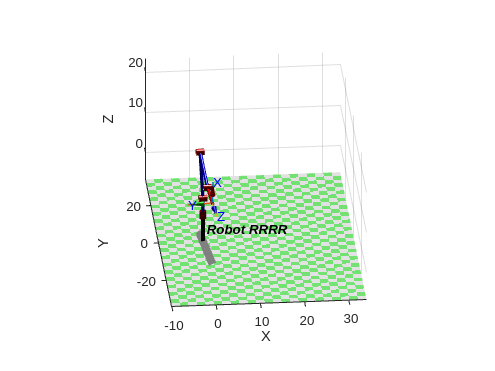

%figure(4)
Robot3.plot([-85*pi/180 20*pi/180 -55*pi/180 17*pi/180])


plot_options4 = {'workspace',ws,'scale',.5,'view',[-5 25]...
    ,'tilesize',2,  'ortho', 'lightpos',[2 2 10] };
Robot4 = SerialLink(L,'name','Robot RRRR','plotopt',plot_options4)

 
Robot4 = 
 
Robot RRRR (4 axis, RRRR, stdDH, slowRNE)                        
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          4|          0|      1.571|          0|
|  2|         q2|          0|       10.5|          0|      1.571|
|  3|         q3|          0|       10.5|          0|     -1.396|
|  4|         q4|          0|        6.5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1           

Robot4.tool=trotz(pi/2)*trotx(pi/2)

 
Robot4 = 
 
Robot RRRR (4 axis, RRRR, stdDH, slowRNE)                        
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          4|          0|      1.571|          0|
|  2|         q2|          0|       10.5|          0|      1.571|
|  3|         q3|          0|       10.5|          0|     -1.396|
|  4|         q4|          0|        6.5|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  0  0  1  0              
          0         0  1  0  0           1  0  0  0              
       9.81         0  0  1  0           0  1  0  0              
                    0  0  0  1           0  0  0  1           

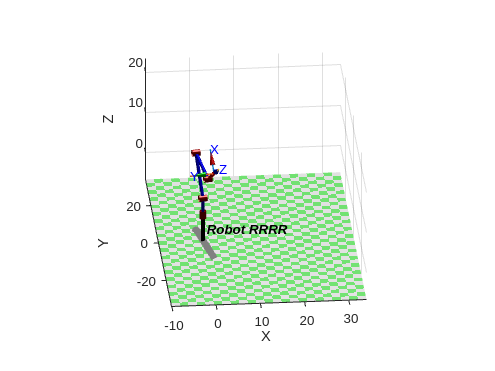

%figure(5)
Robot4.plot([-80*pi/180 35*pi/180 -55*pi/180 45*pi/180])